# Neural Networks Part 1

## What are neural networks?

**Neural networks** are a set of algorithms that are inspired by neural circuits in the brain. These algorithms can be computationally intensive, and have recently exploded in popularity due to advances in computing technology. 

Neural networks work by taking linear combinations of predictors to construct new representations of our features. Non-linear functions are applied to the new features to model the potential non-linearity in the dataset. This family of learning methods can be used for classification and regression problems.

### Modern applications of neural networks

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). The main advantages of neural networks are the following:

- They can detect nonlinear relationships and interactions between predictor variables

- The mathematics underpinning neural networks relies less on statistical assuptions we usually impose in other models

- Neural networks are modular, and many architectures are available to model different problems

### Common components and notation of a neural network

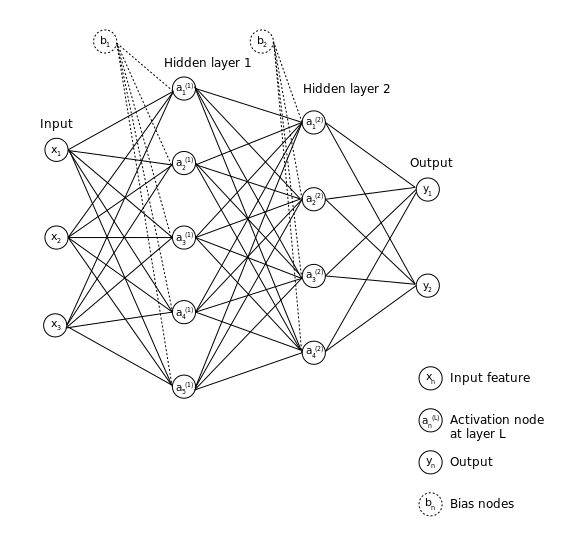

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, where information flows forward from the input to the output, and no information feeds back into the network. 

#### The input layer

Each node in the **input layer** represents a feature in the training data ($X_{\textrm{train}}$). In our data array, each column while each edge corresponds to a **weight** vector. Further, we can choose to add more flexibility into the model by introducing some **bias** values. When we move forward in our computations, we'll be solving equations that are analagous to linear regression expression $X^T \cdot \mathrm{weights}+\mathrm{bias}$.

#### The hidden layer(s)

The hidden layer is where the new values are stored from taking linear combinations of features from the input layer and applying non-linear transformations. These nodes are are known as **activation nodes**, and they represent a single new feature. 

A neural network with a single hidden layer is known as a **shallow neural network**. However, we can add more complexity in the model by adding more hidden layers. Neural networks with more than 1 hidden layer are known as **deep neural networks** (DNNs), and the application of DNNs is known as **deep learning**. 

**The output layer**

From the last hidden layer, the values are transformed once more to the **output layer**. Here, we can use rules to turn these values into labels for a classification problem, or keep the raw values / probabilities in a regression problem. 

To illustrate the main concepts underpinning neural networks for the next two lectures, we'll code up a shallow feedforward neural network from scratch. There are three main phases in a feedforward neural network that we'll go over for the remaining lecture: 

- Constructing new features in forward propagation

- Evaluating the performance of forward prop using a cost function

- Tuning / correcting model parameters using backward propagation

## Step 1: Constructing new features using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively computing linear combinations of the input fed into each layer, followed by a non-linear transformation of the combined features. This is repeated for each hidden layer until we reach the output layer.

### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset `X` with 20 observations and 3 predictor variables. We are also assuming that there is 1 activation node in the hidden layer. 

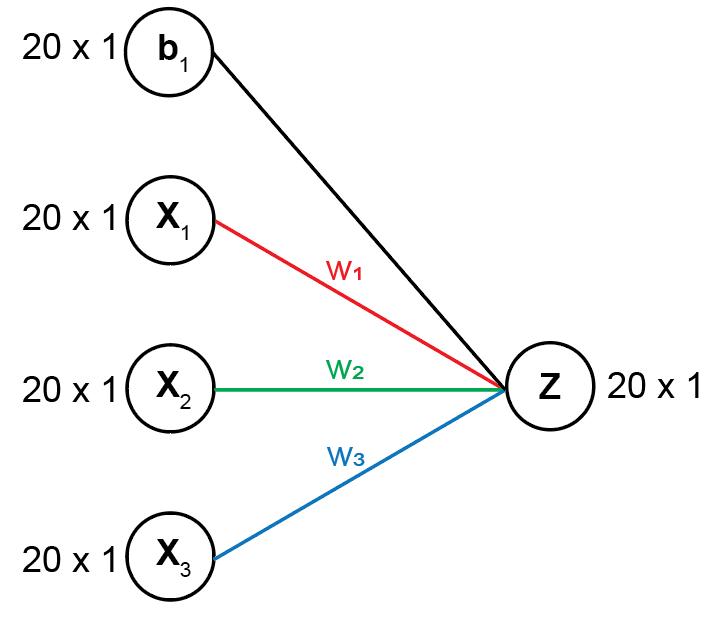

#### Analogy to linear regression

The formula to take a linear combination of predictors is shown below. The new features are stored in the variable `Z`.


$$Z=Xw^T +b$$


While this problem is slightly different from a linear regression problem in that we are solving for the output `Z` rather than using `X` and `Z` to estimate our coefficients, we actually have the same objective, and we're trying to estimate two parameters: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

#### Impact of weights on the new feature `Z` generated by the neural network 

For now, let's see how the two parameters $w$ and $b$ affect the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take the linear combinations with 1 to 3 weights and biases of different values. 

% Initialize inputs using random numbers using a fixed random number generator (rng)
% for reproducibility
rng(2);
X = normrnd(0, 1, [20, 3])

X =    -0.1242    0.0125    1.4454
   -2.5415   -1.0163    0.0000
    0.2772   -0.1156    2.8467
   -0.1960   -0.7763   -0.3859
   -0.1962   -1.1398    0.1502
   -0.3057    0.3198   -0.3172
   -1.1289   -0.5715   -0.1628
    0.1942   -1.6300    0.8194
   -0.6071   -0.9364    0.0817
   -0.8284   -0.2786    1.9564


b = randn([20, 1])

b =     1.1527
    0.3926
    0.7993
   -1.9146
   -0.5855
    0.0593
   -0.5918
   -2.4356
    1.8796
   -0.1841


#### Solution using 1 weight vector

The following network diagram using 1 weight value is shown below:

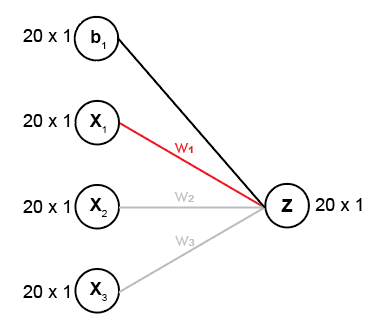

Which is equivalent to solving the following set of equations:


$$Z=X_1 w_1 +b$$


As you can see, the new feature $Z$ will most resemble $X_1$, shown in the scatter plot below.

% Weight vectors
w = [1, 0, 0] % Only 1 weight

w =      1     0     0


Z1 = X * w' + b

Z1 =     1.0285
   -2.1489
    1.0765
   -2.1106
   -0.7817
   -0.2464
   -1.7207
   -2.2414
    1.2725
   -1.0125


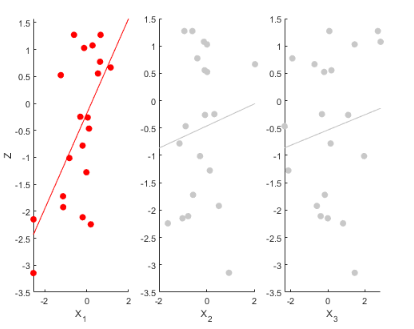

#### Solution using 2 weight vectors

If we include two weights, the network will look like the following diagram:

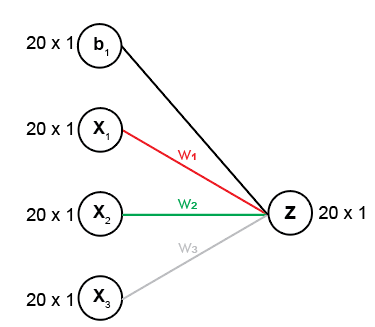

And the system of equations will look like the following:


$$Z=X_1 w_1 +X_2 w_2 +b$$


You will notice that there is a stronger correlation between the new feature $Z$ and $X_2$, as it is assigned a higher weight.

% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1, 2, 0] % 2 weights only

w =      1     2     0


Z2 = X * w' + b

Z2 =     1.0535
   -4.1814
    0.8453
   -3.6632
   -3.0614
    0.3931
   -2.8636
   -5.5014
   -0.6003
   -1.5698


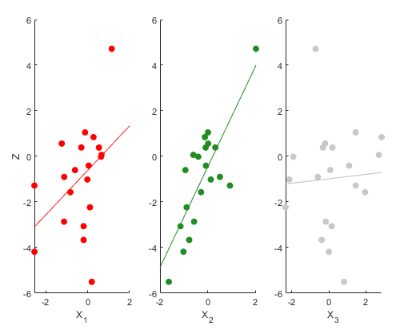

#### Solution using 3 weight vectors

Finally, let's include a fully connected hidden layer with all 3 weights.

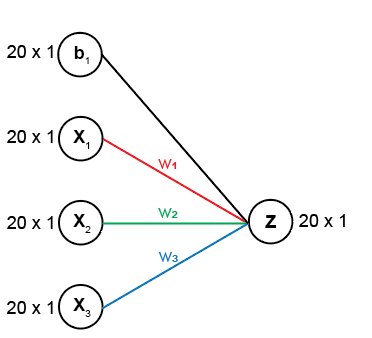

Where the complete set of linear equations to solve will be:


$$Z=X_1 w_1 +X_2 w_2 +X_3 w_3 +b$$


% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1; 2; -5]; % All 3 weights
Z3 = X * w + b

Z3 =    -6.1737
   -4.1815
  -13.3883
   -1.7339
   -3.8122
    1.9791
   -2.0497
   -9.5984
   -1.0088
  -11.3516


We have a new complex feature that is positively correlated with $X_1$ and $X_2$, but negatively correlated with $X_3$,

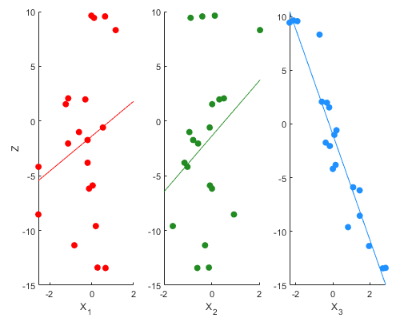

#### Overall impact of w on Z and key points

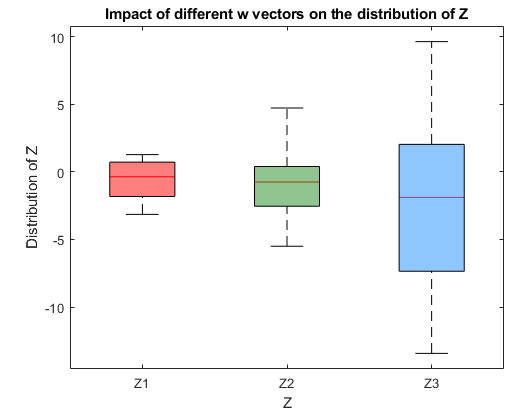

As you can see with the boxplot above, different combinations of weights dramatically the distribution of the final computed predictor `Z`, and creates more complex features`.` The weights are a really important parameter to tune in the model.

#### How do we initialize the weights and biases in practice?

Without knowing the true relationship between the predictor and response variables, we need to initialize the weight and bias parameters somehow. It turns out that[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters than setting them to all zero or one. We'll discuss why we need to initialize neural networks with small and random values for these parameters in the next lecture.  

### Non-linear transformations using an activation function

In this section, we'll discuss different ways to add non-linearity into the computed variable `Z`, and the advantages / disadvantages of each method.

#### The sigmoid activation function

One way to transform the data is to use the sigmoid activation function (aka logit transformation) to transform our data into probabilities with values ranging from [0, 1]. The formulation of the sigmoid activation function is simply:


$$\mathrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


And the shape of the sigmoid distribution is shown below:

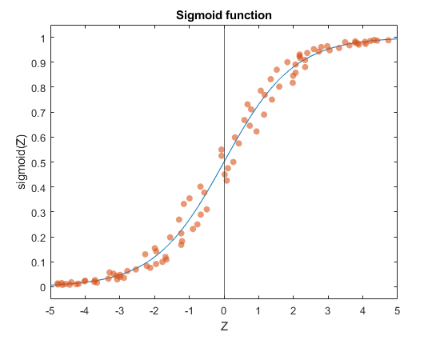

To access all the activation functions described in this lecture, we can use the `activationFnc` script provided in the project folder (documentation described below) to transform our values.

**Applying the sigmoid activation function to **`Z`** values obtained from changing **`w`

Let's see what happens when we apply the sigmoid activation function the three Z values we computed previously.

% Compute y using the Z1 cell array containing the results from using different w values
Z = [Z1, Z2, Z3] % Store all Z values in single array to perform 1 computation
A = activationFnc(Z, 'Sigmoid') % Scaled from 0 -> 1 using sigmoid activation function

As we add additional weight parameters, the transformed values tend to converge faster towards either 0 and 1. This feature of the sigmoid activation function is especially useful for binary classification, where we need to draw out a decision boundary between two classes.

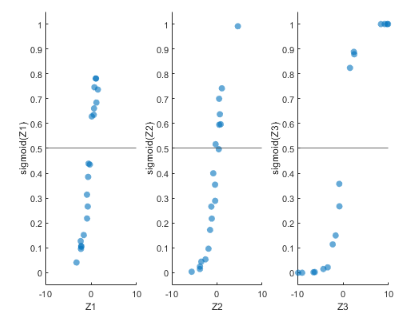

### Rectified linear units (ReLUs) 

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. When correcting our parameters in back propagation (covered in the next section), correcting these extremely small values result in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to optimizing neural network parameters using gradient descent.

- Further, our values are between 0 and 1. This is not really useful for regression problems.

Thus, people have been turning to the ReLU as the preferred activation function, especially for more complex neural network architectures. The formulation of the **ReLU** is shown below, and is really simple:


$$\mathrm{ReLU}\left(z\right)=\left\lbrace \begin{array}{cc}
z & \mathrm{if}\;z>0\\
0 & \mathrm{if}\;z\le 0
\end{array}\right.$$


This basically sets negative values to 0, while leaving the original transformed value intact. The ReLU activation function has the following non-linear distribution shape:

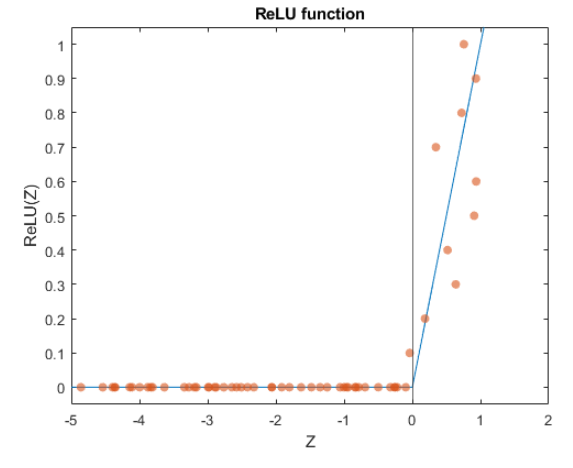

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- The correction term in back propagation is not infinitesimally small. This rectifies the vanishing gradient problem.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

### Leaky rectified linear units (Leaky ReLUs) 

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution shape:

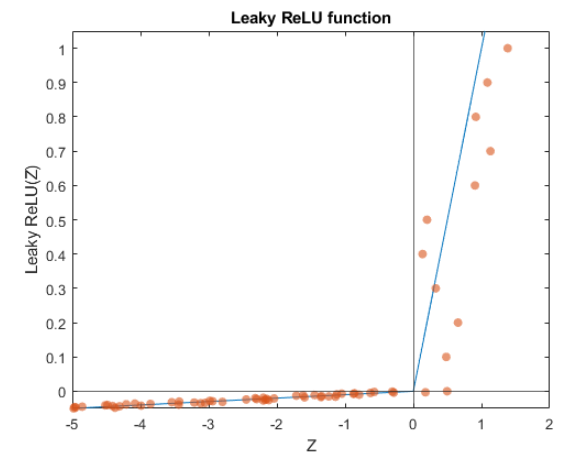

Now that we have covered a single round of combing features and adding non-linearity to the combined features, we have the tools to run a full round of forward propagation. 

### A single round of forward propagation

Let's now put all of these concepts together to run 1 round of forward propagation with **no hidden layer** using a breast cancer dataset built into MATLAB. Without the hidden layer, we're performing logistic regression using forward propagation!

#### Description of breast cancer dataset

The dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. We'll explore the dataset in the codeblock below

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

clear all;
load cancer_dataset.mat
% View input dataset. Rows = features. Columns = observations
data = array2table(cancerInputs, ...
    "RowNames", {'Clump thickness', 'Uniform Cell size', ...
    'Uniform Cell shape', 'Adhesion', 'Single cell size', ...
    'Bare nuclei', 'Bland chromatin', 'Normal nucleoli', ...
    'Mitoses'})

Z =     1.0285    1.0535   -6.1737
   -2.1489   -4.1814   -4.1815
    1.0765    0.8453  -13.3883
   -2.1106   -3.6632   -1.7339
   -0.7817   -3.0614   -3.8122
   -0.2464    0.3931    1.9791
   -1.7207   -2.8636   -2.0497
   -2.2414   -5.5014   -9.5984
    1.2725   -0.6003   -1.0088
   -1.0125   -1.5698  -11.3516


% View target dataset. Rows = targets. Columns = observations

A =     0.7366    0.7414    0.0021
    0.1044    0.0150    0.0150
    0.7458    0.6996    0.0000
    0.1081    0.0250    0.1501
    0.3139    0.0447    0.0216
    0.4387    0.5970    0.8786
    0.1518    0.0540    0.1141
    0.0961    0.0041    0.0001
    0.7812    0.3543    0.2672
    0.2665    0.1722    0.0000


target = array2table(cancerTargets, ...
    "RowNames", {'Benign', 'Malignant'})

To save space in the code blocks in this lecture, we can use the accessory function `loadCancerData` to do the following steps:

- Load the dataset and target variables

- Transposes the datasets so that features and targets span columns

- Split the dataset and target variables into training and test datasets

- Standardize the input datasets to have a mean = 0 and standard deviation of 1. 

We'll use only 2 activation nodes in the hidden layer. Our (naive) hypothesis is that two activation nodes are able to capture the differences in a 2-class (binary) classification problem. We'll discuss a systematic way to choose the number of hidden nodes needed to optimize the performance of the neural network in the next lecture.

#### Intialize variables needed to run forward propagation

% Set seed for reproducibility
rng(2);

% Load the cancer data
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

% Intialize the hyperparameters 
numberOfHiddenNodes = 2;
actFnc = 'Sigmoid';

% Intialize the weights and biases from input -> hidden layer. 
% w1 size should be number of features x number of activation nodes
w = randn([size(Xtrain, 2), numberOfHiddenNodes])
% b1 size should be number of observations in training data x 1
b = randn([size(Xtrain, 1), 1])

#### Forward propagation

Let's now run forward propagation from the input layer to the output layer:

Z = Xtrain * w + b
A = activationFnc(Z, actFnc)
% A is the final predicted value for this logistic regression model
ypred = A;

Now we need to now see how well our model performed using a cost function.

## Step 2: Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **Cross-Entropy cost function.**

### **Cross-Entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ are number of observations, $y_{\textrm{train}}$ is the response variable, and $y_{\textrm{pred}}$ is a vector of the predicted value from forward propagation. 

The **cost** value (`J)` can be computed using the `costFunction` function provided. The docstring is provided below:

% There will be two loss values: one for the malignant target and the other

data = 9×699 table
                          cancerInputs1    cancerInputs2    cancerInputs3    cancerInputs4    cancerInputs5    cancerInputs6    cancerInputs7    cancerInputs8    cancerInputs9    cancerInputs10    cancerInputs11    cancerInputs12    cancerInputs13    cancerInputs14    cancerInputs15    cancerInputs16    cancerInputs17    cancerInputs18    cancerInputs19    cancerInputs20    cancerInputs21    cancerInputs22    cancerInputs23    cancerInputs24    cancerInputs25    cancerInputs26    cancerInputs27    cancerInput

% for the benign target
J = costFunction(Ytrain, ypred, 'Log-Loss')

target = 2×699 table
                 cancerTargets1    cancerTargets2    cancerTargets3    cancerTargets4    cancerTargets5    cancerTargets6    cancerTargets7    cancerTargets8    cancerTargets9    cancerTargets10    cancerTargets11    cancerTargets12    cancerTargets13    cancerTargets14    cancerTargets15    cancerTargets16    cancerTargets17    cancerTargets18    cancerTargets19    cancerTargets20    cancerTargets21    cancerTargets22    cancerTargets23    cancerTargets24    cancerTargets25    cancerTargets26    cancerTargets27   

Now that we have a cost value, we can start to optimize our neural network algorithm using backward propagation.

## Step 3: Optimizing `w` and `b` parameters using backward propagation

After computing the cost, we know how good or how bad our model performed overall. In neural networks, we need to tell the algorithm how to adjust the weight and bias parameters so that the cost goes down in the next iteration,  until we reach a stable minimum cost value. This process is called **back propagation**, and the optimization algorithm we use to update the weights and the biases is **gradient descent**. 

### Finding the gradients dW and db using back propagation

The objective of back propagation is to determine how much we should change `w` and `b` such that we minimize the cost. Thus, we need to find an expression that allows us to relate the cost back to the parameter`. `The **gradient**, or the values from solving partial differential equations of the cost with respect to W ($\frac{\vartheta J}{\vartheta W}$) and b ($\frac{\vartheta J}{\vartheta b}$) will tell us how much error a specific activation node contributes to the overall model error.

#### Intuition for back propagation 

Formulated below are the expressions needed to solve $\frac{\vartheta J}{\vartheta W}$ and  $\frac{\vartheta J}{\vartheta b}$ for each layer:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

Let's consider the gradient $\frac{\vartheta J}{\vartheta W}$ (the same logic applies for $\frac{\vartheta J}{\vartheta b}$) and work backwards from the output layer to the input layer. There are three places where the model can go wrong: 

- From the output layer to the hidden layer ($\frac{\vartheta J}{\vartheta y}$). A natural expression to compute this error is computing $Y_{\mathrm{pred}} -Y_{\mathrm{train}}$.

- From the activation function ($\frac{\vartheta y}{\vartheta Z}$). This expression changes with different activation functions.

- From computing `A` with `w` ($\frac{\vartheta Z}{\vartheta W}$)

As you can see, each layer is chained together. Fortunately, because we know how the network is connected, we can figure out partial differential terms that will connect the cost to any given weight or bias parameter that needs to be adjusted to lower the cost. We won't go over the derivation for each term (honestly, you can probably just Google them), but in practice, we would work these differential equations individually and use the chain rule to compute the gradients. 

#### Derivative terms for back propagation in a logistic regression model

The following set of equations are used in our logistic regression model to compute the gradients for each parameter (denoted as `dw` and `db). `Because we're comparing our predictions directly against our training set, we don't have to compute the error from the activation function.

- 
$$\mathrm{dZ}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$$


- 
$$dW=\mathrm{dZ}\cdot {X_{\mathrm{train}} }^T \cdot \frac{1}{m}$$


- 
$$\;\mathrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ}\right)$$


### Back propagation 

Now let's codify the expressions above to run back propagation. First we need to compute the error from the outermost layer: $\mathrm{dZ}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$

dZ = ypred - Ytrain

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $dW=\mathrm{dZ}\cdot {X_{\mathrm{train}} }^T \cdot \frac{1}{m}$

m = size(Xtrain, 1) % m = number of observations in training set
dW = (1/m) .* (Xtrain' * dZ)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\mathrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ}\right)$$
 

db  = (1/m) .* sum(dZ, 2)

We have just completed the first iteration of back propagation, which relates the cost value J back to the parameters w and b. The last step we need to do is to update the weights and biases. We can do that using the **gradient descent** optimization algorithm.

### Optimizing parameters `W` and `b` using gradient descent

The objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two update equations:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\mathrm{learning}\;\mathrm{rate}\cdot \mathrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}\;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot \mathrm{db}\right)
\end{array}$$
 

where the learning rate hyperparameter is a positive constant value that controls how fast we move along the gradient. Further, `dW` and `db` are the gradients we computed from back propagation. 

We can perform gradient descent for `w` and `b` using the code below:

learning_rate = 0.05;
w = w - (learning_rate .* dW)
b = b - (learning_rate .* db)

We have just completed a single round of training and optimizing a logistic regression model using forward and back propagation. 

## Optimizing the logistic regression model using forward and backward propagation

Now that we did a single pass of forward and backward propagation with our logistic regression model, let's make an algorithm that uses all the components we described so far to optimize the two parameters `w` and `b` after 500 iterations. In machine learning jargon, an iteration of forward and backward prop is called an **epoch**:

% Intialize variables
epoch = 500; learning_rate = 0.05;

w =    -0.1741    1.4754
   -1.4407    0.4140
   -0.0709    0.4951
   -1.3681    2.1199
   -1.4625   -0.4965
   -0.0212    0.4568
    1.2875   -0.3635
   -2.7914    0.9546
   -1.3112    0.4000


m = size(Xtrain, 1); numberOfHiddenNodes = 2;
actFnc = 'Sigmoid';

b =    -0.5168
    1.0543
   -0.9014
    0.3487
   -0.0283
    0.3249
    0.3039
    0.4992
    0.0155
   -1.5946


w = randn([size(Xtrain, 2), numberOfHiddenNodes]);
b = randn([size(Xtrain, 1), 1]);

for i = 1:epoch % Iterate 500 times

Z =     3.6998   -4.2524
    5.8156   -2.8351
    3.1298   -3.0658
   -7.0401    6.1924
    3.0049   -1.5801
    2.3786   -3.2112
  -15.3596    7.0886
    5.1368   -2.3428
    4.5914   -2.3027
   -9.8762    3.3865


    % Forward propagation

A =     0.9759    0.0140
    0.9970    0.0555
    0.9581    0.0445
    0.0009    0.9980
    0.9528    0.1708
    0.9152    0.0387
    0.0000    0.9992
    0.9942    0.0876
    0.9900    0.0909
    0.0001    0.9673


    Z = Xtrain * w + b;
    ypred = activationFnc(Z, actFnc);
    
    % Cost evaluation -> store the costs for plot
    J(i, :) = costFunction(Ytrain, ypred, 'Log-Loss');
    
    % Back propagation
    dZ = ypred - Ytrain;
    dW = (1/m) .* (Xtrain' * dZ);
    db  = (1/m) .* sum(dZ, 2);
    
    % Gradient descent
    w = w - (learning_rate .* dW);
    b = b - (learning_rate .* db);
end

J =     0.2796    0.2001


Let's now plot the cost curve using the cost values `J` against the number of epochs:

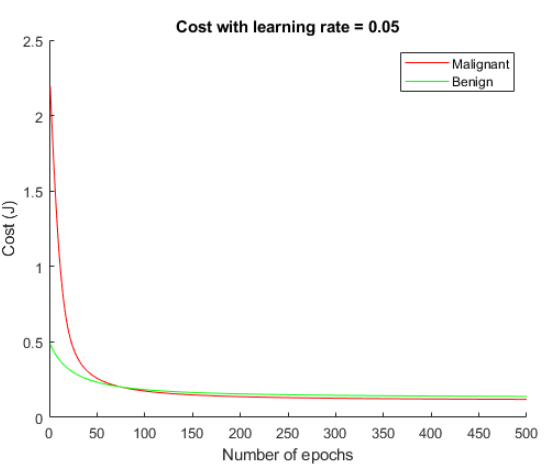

The cost value of using a logistic regression model with forward and backward propagation begins to approach a minimum value around 500 epochs. How do the probability values of each class we predict look?

ypred

dZ =    -0.0241    0.0140
   -0.0030    0.0555
   -0.0419    0.0445
    0.0009   -0.0020
   -0.0472    0.1708
   -0.0848    0.0387
    0.0000   -0.0008
   -0.0058    0.0876
   -0.0100    0.0909
    0.0001   -0.0327


Several values are very close to 0 or 1, indicating that we made a good classifier. Let's transform these probabilities to labels {1, 0} for each respective class, using a p = 0.5 as the decision boundary and compute an accuracy for both classes:

% Label encoding
ypred(ypred > 0.5) = 1;

m = 559

ypred(ypred < 0.5) = 0;

dW =     0.0597   -0.0135
    0.0206   -0.0403
    0.0344   -0.0409
    0.0048   -0.0086
   -0.0107   -0.0433
    0.0657   -0.0556
    0.0566   -0.0628
   -0.0140   -0.0298
   -0.0030   -0.0198


accuracy = (1 - sum(abs(ypred - Ytrain)) / size(ypred, 1)) .* 100

#### Derivative terms for back propagation in a shallow neural network 

The following set of equations are used in our shallow neural network to compute the gradients for each parameter (denoted as `dw2`, `dw1`, and `db1).`

**Output layer to hidden layer: **

- 
$$\textrm{dZ2}=\textrm{A2}-Y_{\textrm{train}} \;$$


- 
$$d\mathrm{W2}=\mathrm{dZ2}\cdot {\mathrm{A1}}^T \cdot \frac{1}{m}$$


- $\;\textrm{db2}=0$ (We did not introduce bias to the last layer)

**Hidden layer to input layer: **

- 
$$\mathrm{dZ1}={\mathrm{W2}}^T \cdot \mathrm{Z2}\cdot g^{\prime } \left(\mathrm{Z1}\right)$$


- 
$$d\mathrm{W1}=\mathrm{dZ1}\cdot {X_{\mathrm{train}} }^T \cdot \frac{1}{m};$$


- 
$$\;\mathrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ1}\right)$$


As noted earlier, the activation function does have its own error term $g^{\prime } \left(\textrm{Z1}\right)$. For the sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\left(1-{\textrm{A2}}^2 \right)$. However, the ReLU and leaky ReLU are nice in that there is no derivative! Instead, we can use the following rule set:


$${g^{\prime } \left(Z\right)}_{\mathrm{ReLU}\;\mathrm{or}\;\mathrm{leaky}\;\mathrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \mathrm{if}\;Z>0\\
0 & \mathrm{if}\;Z\le 0
\end{array}\right.$$


#### Next let's back propagate from the hidden layer to the input layer

dZ1  = (w2 * dZ2') .* (1 - A1.^2)'

db =    -0.0181
    0.0939
    0.0047
   -0.0021
    0.2211
   -0.0824
   -0.0015
    0.1463
    0.1447
   -0.0584


dW1  = (1/m) .* Xtrain' * dZ1'
db1  = (1/m) .* sum(dZ1', 2)

w =    -0.1771    1.4760
   -1.4417    0.4160
   -0.0726    0.4971
   -1.3684    2.1203
   -1.4620   -0.4943
   -0.0245    0.4596
    1.2847   -0.3603
   -2.7907    0.9561
   -1.3111    0.4010


b =    -0.5168
    1.0543
   -0.9014
    0.3487
   -0.0283
    0.3250
    0.3039
    0.4992
    0.0155
   -1.5946


ypred =     0.9719    0.0043
    0.9827    0.0118
    0.8851    0.0050
    0.0055    0.9927
    0.9240    0.0661
    0.9930    0.0525
    0.0000    1.0000
    0.9505    0.0119
    0.9764    0.0431
    0.0089    0.9999


accuracy =    96.7800   95.7066


Unrecognized function or variable 'w2'.

## Summary

We have covered how neural networks work under the hood, and coded a shallow neural network from scratch. In the next lecture, we'll combine what we've learned in this lecture and train a shallow neural network using the breast cancer dataset described in this lecture. We will also cover some of the issues commonly encountered in training a neural network as well as how to optimize the hyperparameters of a neural network. Finally, we'll benchmark the neural network against a logistic regression classifier.

## Additional reading and references 

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).